%clc, clear variables

## model

Ts = 1/20e3;

% parameters
R = 4.7e3;  % Ohm
C = 470e-9; % F

## step response measurement

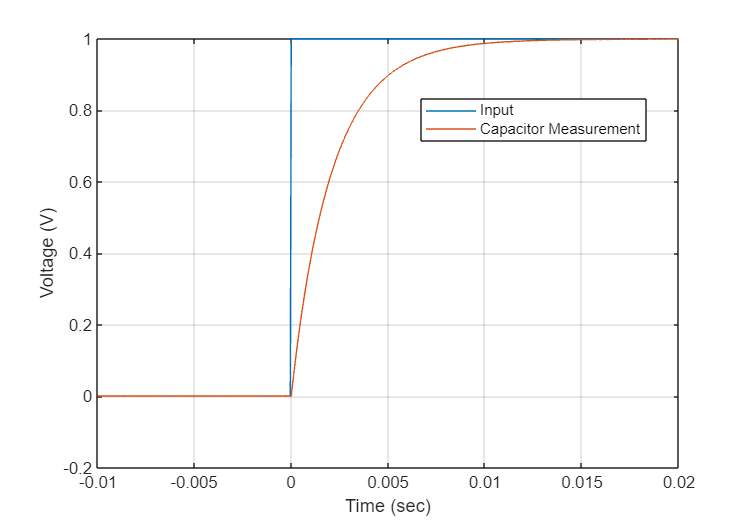

% step response measurement
% - unit step starting at 0.05 sec
% - measurement time 0.10 sec
load step_meas_00.mat % save step_meas_00 data_meas

figure(1)
plot(data_meas.time-0.05, data_meas.signals(1).values), grid on, hold on
plot(data_meas.time-0.05, data_meas.signals(2).values), hold off
xlim([-0.01,0.02])
xlabel('Time (sec)')
ylabel('Voltage (V)')
legend('Input', 'Capacitor Measurement', ...
    'Location', 'best')

## step response comparison

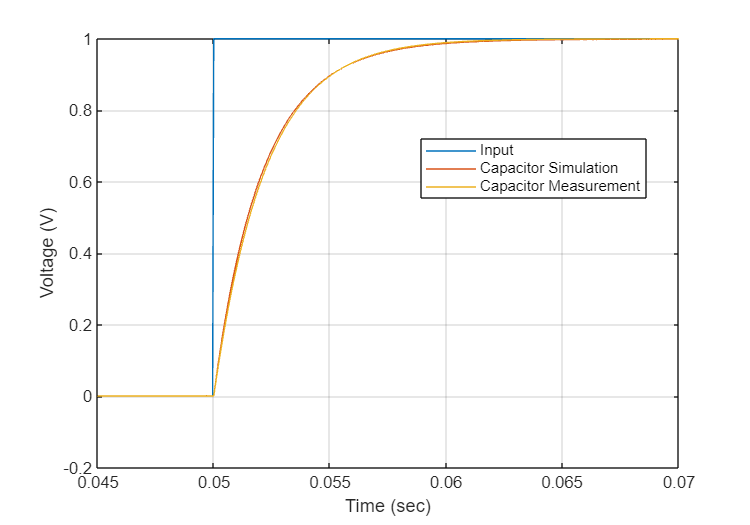

sim('p1_rc_sim')
% step response simulation (Simulink)
%load step_sim_00.mat % save step_sim_00 data_sim

figure(2)
plot(data_meas.time, data_meas.signals(1).values), grid on, hold on
plot(data_meas.time, data_meas.signals(2).values)
plot(data_sim.time, data_sim.signals(2).values), hold off
xlabel('Time (sec)')
ylabel('Voltage (V)')
legend('Input', 'Capacitor Simulation', ...
    'Capacitor Measurement', ...
    'Location', 'best')
xlim([0.045 0.07])

## model as tf-object and step function

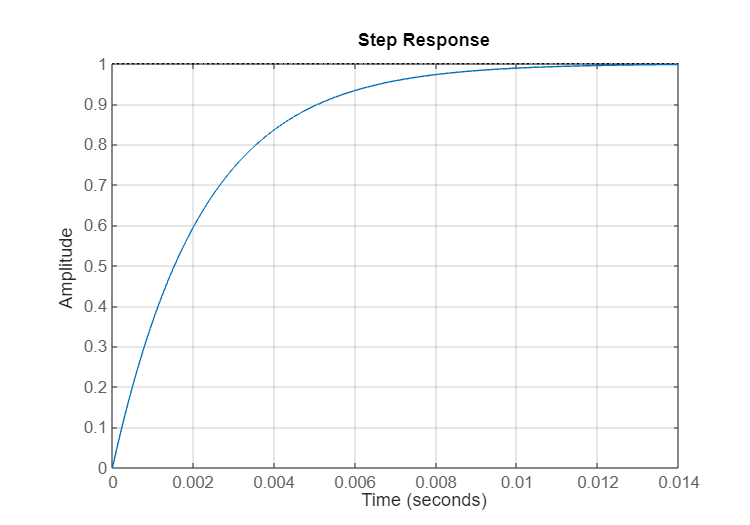

% transfer function
s = tf('s');
Grc_mod = 1 / (R*C*s + 1);
figure(2)
step(Grc_mod), grid on

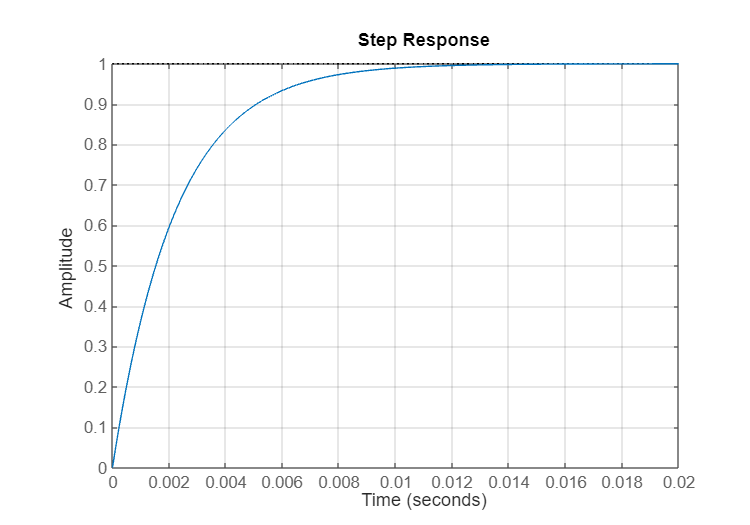


t = linspace(0,0.02,1000)';

figure(3)
step(Grc_mod,t), grid on

## frequency response measurments

% time constant
T = R*C;
% cutoff frequency
wg = 1/T;

% excitation
w0 = [1, wg, 1e3];
uE_hat = [1.0, 2.0, 3.0];

% frequency in hz
f0 = w0 / (2*pi)

f0 =     0.1592   72.0484  159.1549


T_p = 1 ./ f0

T_p =     6.2832    0.0139    0.0063



% system answer
uC_hat = [1.000, 1.403, 1.244]; % <- fill values here

% magnitude |G(w)|
G_mag = uC_hat ./ uE_hat

G_mag =     1.0000    0.7015    0.4147


G_mag_db = db(G_mag)

G_mag_db =          0   -3.0794   -7.6460



% phase angle(G(w)))
dT = [0.0, 1.728e-3, 1.192e-3]; % <- fill values here
dT_ms = dT * 1e3

dT_ms =          0    1.7280    1.1920


G_pha = -dT .* w0;
G_pha_Deg = G_pha * 180/pi

G_pha_Deg =          0  -44.8199  -68.2966



% G(w) = |G(w)| * exp(i * angle(G(w)))
G0 = G_mag .* exp(1i * G_pha)

G0 =    1.0000 + 0.0000i   0.4976 - 0.4945i   0.1533 - 0.3853i


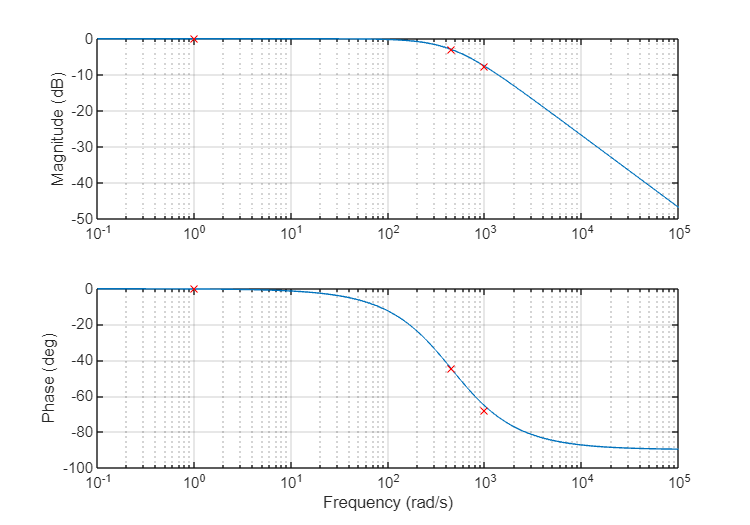


% frequency response model
w = logspace(-1, 5, 1e3)';
Grc_mod_freq = 1 ./ (R*C*1i*w + 1);

figure(4)
subplot(211)
semilogx(w, 20 * log10(abs( Grc_mod_freq ))), grid on, hold on
semilogx(w0, 20 * log10(G_mag), 'rx'), hold off
%set(gca, 'XScale', 'log')
ylabel('Magnitude (dB)')
% axis([2*pi*0.1, 2*pi*1e4, -60 20])
subplot(212)
semilogx(w, 180/pi * (angle( Grc_mod_freq ))), grid on, hold on
semilogx(w0, 180/pi * G_pha, 'rx'), hold off
% set(gca, 'XScale', 'log')
ylabel('Phase (deg)'), xlabel('Frequency (rad/s)')

% axis([2*pi*0.1, 2*pi*1e4, -95, 5])

## model as tf-object and bode function

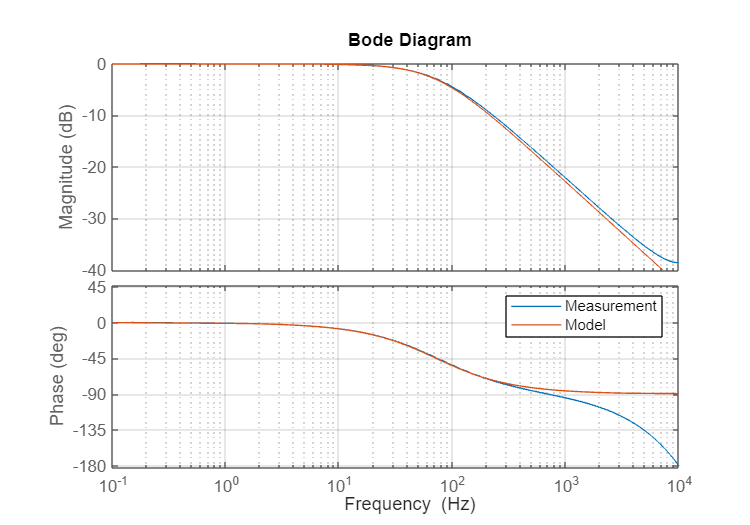

load G_00.mat % save G_00 G

% Grc_mod_with_delay = Grc_mod;
% Grc_mod_with_delay.InputDelay = 50e-6 / 2; % Ts / 2

figure(5)
bode(G, Grc_mod), grid on
legend('Measurement', ...
    'Model', ...
    'Location', 'best')

% bode(G, Grc_mod, Grc_mod_with_delay)
% legend('Measurement', ...
%     'Model', ...
%     'Model with Deadtime', ...
%     'Location', 'best')